# Cleaning Workspace

clear;
close all;
clc;

## Ploting Parameters

linewidth  = 2;
fontname   = 'Times New Roman';
fontsize   = 20;
markersize = 10;

colors = [0.0000 0.0000 0.0000;
          0.0000 0.4470 0.7410;
          0.8500 0.3250 0.0980;
          0.9290 0.6940 0.1250;
          0.4940 0.1840 0.5560;
          0.4660 0.6740 0.1880;
          0.3010 0.7450 0.9330;
          0.6350 0.0780 0.1840];

# Communication System

## Data Transmission Parameters

Parameters related to the data transmission, e.g., number of bits, constellation size, number of subcarriers, and number of transmitted blocks.

SNR   = 0:5:30;                    % Signal-to-noise ratio in dB
N_SNR = length(SNR);               % Length of SNR

B = 3;                             % Number of bits in a symbol
Q = 2^B;                           % Constellation size

L = 10;                            % Channel length in samples

M = 32;                            % Number of subcarriers
K = L;                             % Prefix length in samples
N = M+K;                           % Data block length

N_BLK = 1000;                      % The number of transmitted data blocks

N_EQ  = 2;                         % Number of equalizers

N_FFT  = 1024;

freq_N = 2*pi*linspace(-0.5,0.5,N_FFT);
freq_M = 2*pi*linspace(-0.5,0.5,M);

BER = zeros(N_SNR,N_EQ,4);

A_cp = [zeros(K,M-K) eye(K); eye(M)];
R_cp = [zeros(M,K) eye(M)];

A_zp = [eye(M); zeros(K,M)];
R_zp = [eye(M) [eye(K); zeros(M-K,K)]];

x  = zeros(N*N_BLK,4);
Px = zeros(4,1);

y_p       = zeros(N,N_BLK,4,N_SNR);
m_mod_hat = zeros(M,N_BLK,N_EQ,4,N_SNR);
m_bit_hat = zeros(B*M*N_BLK,N_EQ,4,N_SNR);

## Transmitter

m_bit = randi([0 1],B*M*N_BLK,1);          % Random data bits
m_mod = qammod(m_bit,Q,'InputType','bit'); % Q-QAM modulation
m_mod = reshape(m_mod,M,N_BLK);

### CP-SC-FD

s = A_cp*m_mod;                            % Single-carrier symbols with cyclic prefix

x(:,1) = reshape(s,[],1);                  % Parallel to serial conversion
Px(1)  = norm(x(:,1))^2/length(x(:,1));    % Average transmission power

### ZP-SC-FD

s = A_zp*m_mod;                            % Single-carrier symbols with zero-padding

x(:,2) = reshape(s,[],1);                  % Parallel to serial conversion
Px(2)  = norm(x(:,2))^2/length(x(:,2));    % Average transmission power

### CP-OFDM

s = sqrt(M)*A_cp*ifft(m_mod);              % OFDM symbols with cyclic prefix

x(:,3) = reshape(s,[],1);                  % Parallel to serial conversion
Px(3)  = norm(x(:,3))^2/length(x(:,3));    % Average transmission power

### ZP-OFDM

s = sqrt(M)*A_zp*ifft(m_mod);              % OFDM symbols with zero-padding

x(:,4) = reshape(s,[],1);                  % Parallel to serial conversion
Px(4)  = norm(x(:,4))^2/length(x(:,4));    % Average transmission power

## Channel

h = randn(L+1,1) +1i*rand(L+1,1);          % Generating FIR channel with i.i.d. Rayleigh distribution and L order
h = h/norm(h);                             % Channel normalization

h_freq = fft(h,N_FFT);                     % Frequency response H(w)
lambda = fft(h,M);                         % Frequency response H(2pim/M)

z = fftfilt(h,x);                          % Filter signal by channel

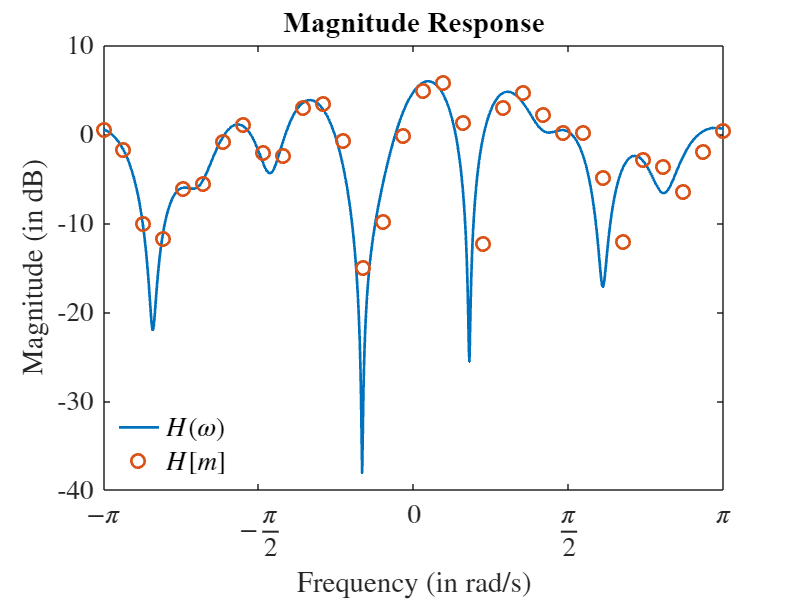

figure;

set(gcf,'position',[0 0 800 600])

plot(freq_N,fftshift(20*log10(abs(h_freq))),'linewidth',linewidth,'markersize',markersize);
hold on;
plot(freq_M,fftshift(20*log10(abs(lambda))),'o','linewidth',linewidth,'markersize',markersize);

title('Magnitude Response','fontname',fontname,'fontsize',fontsize);
xlabel('Frequency (in rad/s)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Magnitude (in dB)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

legend({'$H(\omega)$','$H[m]$'},'fontname',fontname,'fontsize',fontsize,'interpreter','latex','location','southwest')
legend box off

xticks([-pi -pi/2 0 pi/2 pi]);

xlim([-pi,pi]);

set(gca,'ticklabelinterpreter','latex', ...
    'xticklabel',{'$-\pi$','$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$','$\pi$'}, ...
    'fontname',fontname,'fontsize',fontsize);

## Receiver

for snr_ind = 1:N_SNR 
    v  = randn(N*N_BLK,1) + 1i*randn(N*N_BLK,1);           % AWGN noise
    Pv = norm(v)^2/length(v);                              % Average noise power
    
    v_1 = sqrt(((Px(1)/Pv))*(10^(-SNR(snr_ind)/10)))*v;    % True AWGN noise
    v_2 = sqrt(((Px(2)/Pv))*(10^(-SNR(snr_ind)/10)))*v;    % True AWGN noise
    v_3 = sqrt(((Px(3)/Pv))*(10^(-SNR(snr_ind)/10)))*v;    % True AWGN noise
    v_4 = sqrt(((Px(4)/Pv))*(10^(-SNR(snr_ind)/10)))*v;    % True AWGN noise

    y = z + [v_1 v_2 v_3 v_4];                             % Received signal
    
    y_p(:,:,1,snr_ind) = reshape(y(:,1),N,N_BLK);          % Serial to parallel conversion of the CP-SC symbols
    y_p(:,:,2,snr_ind) = reshape(y(:,2),N,N_BLK);          % Serial to parallel conversion of the ZP-SC symbols
    y_p(:,:,3,snr_ind) = reshape(y(:,3),N,N_BLK);          % Serial to parallel conversion of the CP-OFDM symbols
    y_p(:,:,4,snr_ind) = reshape(y(:,4),N,N_BLK);          % Serial to parallel conversion of the ZP-OFDM symbols


### Equalizers

    Equalizer_zf = diag(1./lambda);                                                % ZF equalizer matrix
    Equalizer_mmse = diag(conj(lambda)./(abs(lambda).^2 + 10^(-SNR(snr_ind)/10))); % MMSE equalizer matrix

### CP-SC-FD

    m_mod_hat(:,:,1,1,snr_ind) = ifft(Equalizer_zf*fft(R_cp*y_p(:,:,1,snr_ind)));   % ZF equaliztion
    m_mod_hat(:,:,2,1,snr_ind) = ifft(Equalizer_mmse*fft(R_cp*y_p(:,:,1,snr_ind))); % MMSE equalization
    
    % Q-QAM demodulation

    m_bit_hat(:,1,1,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,1,1,snr_ind),[],1),Q,'OutputType','bit'); % ZF 
    m_bit_hat(:,2,1,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,2,1,snr_ind),[],1),Q,'OutputType','bit'); % MMSE
    
    % Bit-error rate computation

    [~,BER(snr_ind,1,1)] = biterr(m_bit_hat(:,1,1,snr_ind),m_bit); % ZF
    [~,BER(snr_ind,2,1)] = biterr(m_bit_hat(:,2,1,snr_ind),m_bit); % MMSE

### ZP-SC-FD

    m_mod_hat(:,:,1,2,snr_ind) = ifft(Equalizer_zf*fft(R_zp*y_p(:,:,2,snr_ind)));   % ZF equaliztion
    m_mod_hat(:,:,2,2,snr_ind) = ifft(Equalizer_mmse*fft(R_zp*y_p(:,:,2,snr_ind))); % MMSE equalization
    
    % Q-QAM demodulation

    m_bit_hat(:,1,2,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,1,2,snr_ind),[],1),Q,'OutputType','bit'); % ZF
    m_bit_hat(:,2,2,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,2,2,snr_ind),[],1),Q,'OutputType','bit'); % MMSE
    
    % Bit-error rate computation

    [~,BER(snr_ind,1,2)] = biterr(m_bit_hat(:,1,2,snr_ind),m_bit); % ZF
    [~,BER(snr_ind,2,2)] = biterr(m_bit_hat(:,2,2,snr_ind),m_bit); % MMSE


### CP-OFDM

    m_mod_hat(:,:,1,3,snr_ind) = Equalizer_zf*fft(R_cp*y_p(:,:,3,snr_ind))/sqrt(M);   % ZF equalization
    m_mod_hat(:,:,2,3,snr_ind) = Equalizer_mmse*fft(R_cp*y_p(:,:,3,snr_ind))/sqrt(M); % MMSE equalization
    
    % Q-QAM demodulation

    m_bit_hat(:,1,3,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,1,3,snr_ind),[],1),Q,'OutputType','bit'); % ZF
    m_bit_hat(:,2,3,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,2,3,snr_ind),[],1),Q,'OutputType','bit'); % MMSE
    
    % Bit-error rate computation

    [~,BER(snr_ind,1,3)] = biterr(m_bit_hat(:,1,3,snr_ind),m_bit); % ZF
    [~,BER(snr_ind,2,3)] = biterr(m_bit_hat(:,2,3,snr_ind),m_bit); % MMSE


### ZP-OFDM

    m_mod_hat(:,:,1,4,snr_ind) = Equalizer_zf*fft(R_zp*y_p(:,:,4,snr_ind))/sqrt(M);   % ZF equalization
    m_mod_hat(:,:,2,4,snr_ind) = Equalizer_mmse*fft(R_zp*y_p(:,:,4,snr_ind))/sqrt(M); % MMSE equalization
    
    % Q-QAM demodulation

    m_bit_hat(:,1,4,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,1,4,snr_ind),[],1),Q,'OutputType','bit'); % ZF
    m_bit_hat(:,2,4,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,2,4,snr_ind),[],1),Q,'OutputType','bit'); % MMSE
    
    % Bit-error rate computation

    [~,BER(snr_ind,1,4)] = biterr(m_bit_hat(:,1,4,snr_ind),m_bit); % ZF
    [~,BER(snr_ind,2,4)] = biterr(m_bit_hat(:,2,4,snr_ind),m_bit); % MMSE
end

# Ploting Results

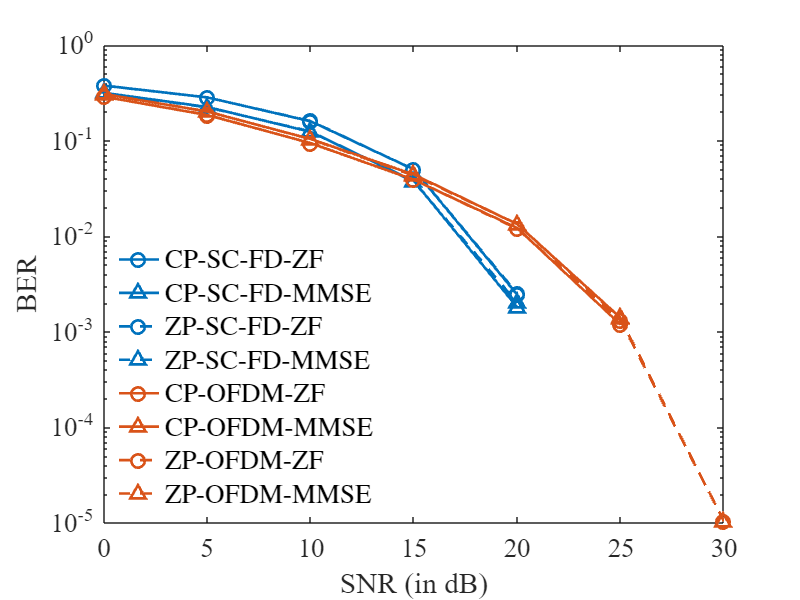

figure;

set(gcf,'position',[0 0 800 600])

semilogy(SNR,BER(:,1,1),'o-' ,'color',colors(2,:),'linewidth',linewidth,'markersize',markersize);
hold on;
semilogy(SNR,BER(:,2,1),'^-' ,'color',colors(2,:),'linewidth',linewidth,'markersize',markersize);
semilogy(SNR,BER(:,1,2),'o--','color',colors(2,:),'linewidth',linewidth,'markersize',markersize);
semilogy(SNR,BER(:,2,2),'^--','color',colors(2,:),'linewidth',linewidth,'markersize',markersize);
semilogy(SNR,BER(:,1,3),'o-' ,'color',colors(3,:),'linewidth',linewidth,'markersize',markersize);
semilogy(SNR,BER(:,2,3),'^-' ,'color',colors(3,:),'linewidth',linewidth,'markersize',markersize);
semilogy(SNR,BER(:,1,4),'o--','color',colors(3,:),'linewidth',linewidth,'markersize',markersize);
semilogy(SNR,BER(:,2,4),'^--','color',colors(3,:),'linewidth',linewidth,'markersize',markersize);

xlabel('SNR (in dB)','fontname',fontname,'fontsize',fontsize);
ylabel('BER','fontname',fontname,'fontsize',fontsize);

legend({'CP-SC-FD-ZF','CP-SC-FD-MMSE','ZP-SC-FD-ZF','ZP-SC-FD-MMSE','CP-OFDM-ZF','CP-OFDM-MMSE','ZP-OFDM-ZF','ZP-OFDM-MMSE'}, ...
    'fontname',fontname,'fontsize',fontsize,'interpreter','latex','location','southwest')
legend box off

% xlim([-5 10]);

set(gca,'fontname',fontname,'fontsize',fontsize);